Given $f=500\mathrm{GHz}$, $D_f =4\mathrm{𝜆}$, and $f_{\mathrm{focal}} =5m$.

1. (1 point) Provide the normalized far field patterns of the circular antenna feed at the two main cuts (E- and H- planes) in dB. Explain what governs the shape of this far field and its variation over the azimuth planes.

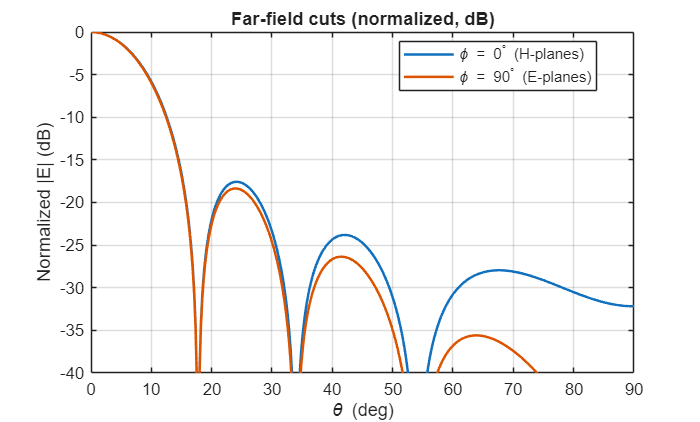

% Constants
f = 500e9;
c0 = 3e8;
lambda_0 = c0 / f;
k0 = 2*pi / lambda_0;

zeta0 = 120*pi;
D_f  = 4 * lambda_0;
a    = D_f / 2;
J_f  = 1;

% Angular grid
num_th = 401;
theta_feed = linspace(eps, pi / 2,  num_th);
phi_feed   = [eps pi/2];
[TH_feed, PH_feed] = meshgrid(theta_feed, phi_feed);

% Feed distance 
r_feed = 1; 
r_feed = r_feed .* ones(size(TH_feed));

% J_FT 
x = k0*a*sin(TH_feed);
J_FT = 2*pi*a^2 .* besselj(1, x) ./ x;  

% Common prefactor
pref = (-2*1j*k0*zeta0*J_f) .* abs(J_FT) .* exp(-1j*k0*r_feed) ./ (4*pi*r_feed);

% Spherical components 
E_theta = pref .* (cos(TH_feed) .* sin(PH_feed));
E_phi   = pref .* (cos(PH_feed));

E_ff = zeros([size(TH_feed), 3]);
E_ff(:,:,1) = 0;        
E_ff(:,:,2) = E_theta; 
E_ff(:,:,3) = E_phi;    

H_theta = -(1/zeta0) * E_phi;
H_phi   =  (1/zeta0) * E_theta;

H_ff = zeros(size(E_ff));    
H_ff(:,:,1) = 0;             
H_ff(:,:,2) = H_theta;        
H_ff(:,:,3) = H_phi;          

% --- Far-field magnitude (total E) on the grid
E_mag = sqrt(abs(E_theta).^2 + abs(E_phi).^2);   % 2 × num_th

% Indices for cuts: phi_feed = [~0, pi/2]
idx_phi0  = 1;   % phi ≈ 0
idx_phi90 = 2;   % phi = pi/2

E0  = E_mag(idx_phi0 , :);
E90 = E_mag(idx_phi90, :);

% Normalize to the peak across BOTH cuts (common normalization)
Emax = max([E0(:); E90(:)]);
E0n  = E0  / Emax;
E90n = E90 / Emax;

% dB (protect against log(0))
floor_lin = 1e-12;
E0_dB  = 20*log10(max(E0n , floor_lin));
E90_dB = 20*log10(max(E90n, floor_lin));

figure;
plot(theta_feed*180/pi, E0_dB,  'LineWidth', 1.5); hold on;
plot(theta_feed*180/pi, E90_dB, 'LineWidth', 1.5);
grid on;
xlabel('\theta (deg)');
ylabel('Normalized |E| (dB)');
ylim([-40 0]); % adjust
xlim([0 90]);
legend('\phi = 0^\circ (H-planes)', '\phi = 90^\circ (E-planes)', 'Location', 'best');
title('Far-field cuts (normalized, dB)');

When there is no reflector present, the shape of the far field pattern only depends on the current density on the aperature, which depends on $D_f$ under the same frequency. 

2. (2 point) Plot the amplitude of the equivalent aperture current distribution for a reflector with 𝑓/𝐷 = 2 in dB. Plot both the magnetic and electric equivalent currents in 2D maps (e.g. a u-v map). Separate these plots into two, one for the x- and one for the y- polarization.

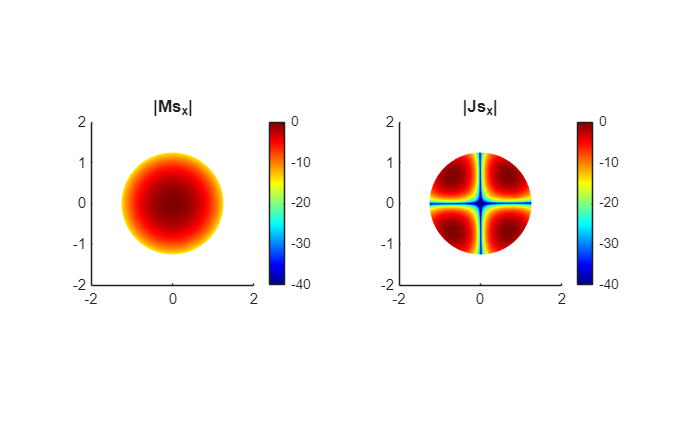

% Old constants
f = 500e9;
c0 = 3e8;
lambda_0 = c0 / f;
k0 = 2*pi / lambda_0;
k = k0;

zeta0 = 120 * pi;
D_f  = 4 * lambda_0;
a    = D_f / 2;
J_f  = 1;

% New constants
f_focal = 5;
f_hash = 2;
D       = f_focal/f_hash;
th0 = 2 * acot(4 * f_hash);

% Angular grid
num_th = 401;
num_ph = 401;
theta_feed = linspace(eps, th0,  num_th); % Only use wave that will be reflected.
phi_feed   = linspace(eps, 2*pi,  num_ph);
[TH_feed, PH_feed] = meshgrid(theta_feed, phi_feed);

% Feed distance 
r_feed = 1; 
r_feed = r_feed .* ones(size(TH_feed));

% J_FT 
x = k0*a*sin(TH_feed);
J_FT = 2*pi*a^2 .* besselj(1, x) ./ x;  

% Common prefactor
pref = (-2*1j*k0*zeta0*J_f) .* J_FT .* exp(-1j*k0*r_feed) ./ (4*pi*r_feed);

% Spherical components 
E_theta = pref .* (cos(TH_feed) .* sin(PH_feed));
E_phi   = pref .* (cos(PH_feed));

% Change to cylindrical coordinates 
RHO_p = 2 .* f_focal .* tan(TH_feed ./ 2);
PH_p = PH_feed;

Ea_rho = -E_theta .* exp(-1j*k*2*f_focal).*cos(TH_feed/2).^2/f_focal;
Ea_phi = -E_phi .* exp(-1j*k*2*f_focal).*cos(TH_feed/2).^2/f_focal;

Ea_x = Ea_rho.*cos(PH_p) - Ea_phi.*sin(PH_p);
Ea_y = Ea_rho.*sin(PH_p) + Ea_phi.*cos(PH_p);

E_a = zeros([size(Ea_x), 3]);
E_a(:, :, 1) = Ea_x;
E_a(:, :, 2) = Ea_y;

n = zeros([size(TH_feed), 3]); 
n(:,:,3) = ones(size(TH_feed));
M = cross(E_a, n, 3);
M_x = M(:, :, 1);
M_y = M(:, :, 2);

J_s = 1/zeta0 * cross(n, cross(n, E_a, 3), 3);
Js_x = J_s(:,:,1);
Js_y = J_s(:,:,2);

U = RHO_p.*cos(PH_p);
V = RHO_p.*sin(PH_p);

figure; 
subplot(1,2,1);
hold on;
axis equal;
surface(U, V, 20*log10(abs(M_x))-max(max(20*log10(abs(M_x)))) , 'linestyle' , 'none' ) ;
title("|Ms_x|");
colormap("jet");
colorbar;
clim([-40 0]);
axis([ -2 2 -2 2]);

subplot(1,2,2);
hold on;
axis equal;
surface(U, V, 20*log10(abs(Js_x))-max(max(20*log10(abs(Js_x)))) , 'linestyle' , 'none' ) ;
title("|Js_x|");
colormap("jet");
colorbar;
clim([-40 0]);
axis([ -2 2 -2 2])

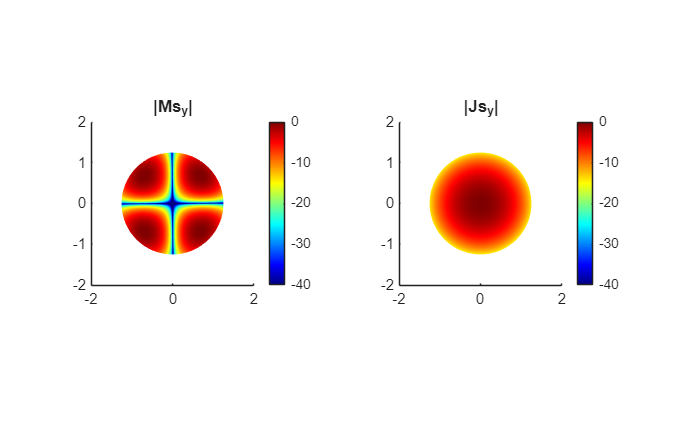



figure
subplot(1,2,1);
hold on;
surface(U, V, 20*log10(abs(M_y)) - max(max(20*log10(abs(M_y)))) , 'linestyle' , 'none' ) ;
axis equal;
axis([ -2 2 -2 2]);
title("|Ms_y|");
colormap("jet");
colorbar;
clim([-40 0]);
subplot(1,2,2);
hold on;
surface(U, V, 20*log10(abs(Js_y)) - max(max(20*log10(abs(Js_y)))) , 'linestyle' , 'none' ) ;
axis equal;
axis([ -2 2 -2 2]);
title("|Js_y|");
colormap("jet");
colorbar;
clim([-40 0]);

It can be found that the UV plots of Js_y and Ms_x are idential and the UV plot of Ms_y and Js_x are idential. This is somewhat expected because both Js and Ms are linked to E_a. In this case, we are working with Love’s formulation. 

3. (2 point) Plot the normalized far field patterns radiated by the parabolic reflector for 𝑓/𝐷 = 1 at the two main cuts (E- and H- planes) in dB. Compare this far field to the one where the equivalent aperture of the reflector has a uniform current distribution, i.e. compare the far field to the corresponding Airy pattern.

Now we are working with Schelkunoff ’s formulation + Image principle to make the calculation easier.

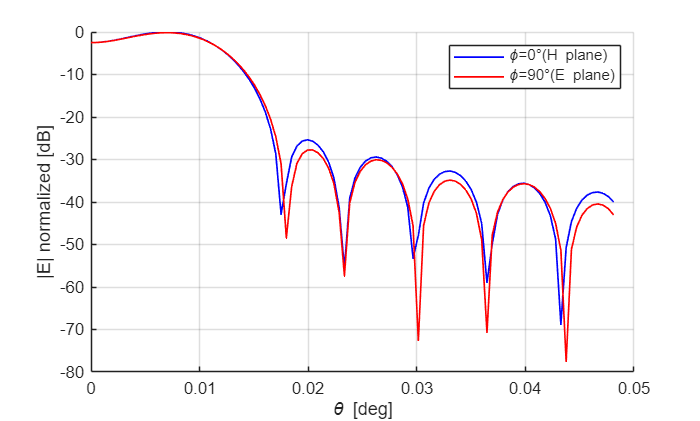

clear; clc;
% Old constants
f = 500e9;
c0 = 3e8;
lambda_0 = c0 / f;
k0 = 2*pi / lambda_0;
k = k0;

zeta0 = 120 * pi;
D_f  = 4 * lambda_0;
a    = D_f / 2;
J_f  = 1;

f_focal = 5;
f_hash = 1;
D       = f_focal/f_hash;
th0 = 2 * acot(4 * f_hash);

% Angular grid
num_th = 401;
num_ph = 401;
theta_feed = linspace(eps, th0,  num_th); % Only use wave that will be reflected.
phi_feed   = linspace(eps, 2*pi,  num_ph);
[TH_feed, PH_feed] = meshgrid(theta_feed, phi_feed);

% Feed distance 
r_feed = 1; 
r_feed = r_feed .* ones(size(TH_feed));

% J_FT 
x = k0*a*sin(TH_feed);
J_FT = 2*pi*a^2 .* besselj(1, x) ./ x;  

% Common prefactor
pref = (-2*1j*k0*zeta0*J_f) .* J_FT .* exp(-1j*k0*r_feed) ./ (4*pi*r_feed);

% Spherical components 
E_theta = pref .* (cos(TH_feed) .* sin(PH_feed));
E_phi   = pref .* (cos(PH_feed));

% Change to cylindrical coordinates 
RHO_p = 2 .* f_focal .* tan(TH_feed ./ 2);
PH_p = PH_feed;

Ea_rho = -E_theta .* exp(-1j*k*2*f_focal).*cos(TH_feed/2).^2/f_focal;
Ea_phi = -E_phi .* exp(-1j*k*2*f_focal).*cos(TH_feed/2).^2/f_focal;

Ea_x = Ea_rho.*cos(PH_p) - Ea_phi.*sin(PH_p);
Ea_y = Ea_rho.*sin(PH_p) + Ea_phi.*cos(PH_p);

E_a = zeros([size(Ea_x), 3]);
E_a(:, :, 1) = Ea_x;
E_a(:, :, 2) = Ea_y;

n = zeros([size(TH_feed), 3]); 
n(:,:,3) = ones(size(TH_feed));
% M = cross(E_a, n, 3);
% M_x = M(:, :, 1);
% M_y = M(:, :, 2);

J_s = 1/zeta0 * cross(n, cross(n, E_a, 3), 3);
Js_x = 2 * J_s(:,:,1);
Js_y = 2 * J_s(:,:,2);

%Far field grid
R_ff = 1000;
ph_ff = [0 pi/2];
th_ff = linspace(0, 7*lambda_0/D, 100);

Eth = zeros(length(ph_ff), length(th_ff));
Eph = zeros(length(ph_ff), length(th_ff));

dth = (pi/2)/(num_th-1);
dphi = (2*pi)/(num_ph-1);
drho = 2 .* f_focal .* tan(dth ./ 2);

for ii = 1:length(th_ff)
    for jj = 1:length(ph_ff)
        
        th  = th_ff(ii);
        ph  = ph_ff(jj);
        
        kx = k*sin(th)*cos(ph);
        ky = k*sin(th)*sin(ph);
        kz = k*cos(th);
        
        phase = exp(1j*(kx*RHO_p.*cos(PH_p) + ky*RHO_p.*sin(PH_p)));
        
        J_FT_x = sum(sum(Js_x .* phase .* RHO_p)) * drho * dphi;
        J_FT_y = sum(sum(Js_y .* phase .* RHO_p)) * drho * dphi;
        
        GF = EJ_SGF(zeta0, k, kx, ky);
        Gxx = GF(:,:,1,1); Gyx = GF(:,:,2,1); Gzx = GF(:,:,3,1);
        Gxy = GF(:,:,1,2); Gyy = GF(:,:,2,2); Gzy = GF(:,:,3,2);
        
        % Far field contributions
        [Eth_x, Eph_x] = farfield(k, R_ff, th, ph, kz, Gxx, Gyx, Gzx, J_FT_x);
        [Eth_y, Eph_y] = farfield(k, R_ff, th, ph, kz, Gxy, Gyy, Gzy, J_FT_y);
        
        Eth(jj, ii) = Eth_x + Eth_y;
        Eph(jj, ii) = Eph_x + Eph_y;
      
    end
end

% Total field
E_ff = sqrt(abs(Eth).^2 + abs(Eph).^2);
E_ff_max = max(max(20*log10(abs(E_ff))));

[~, idx_phi_0]  = min(abs(ph_ff - 0));
[~, idx_phi_90] = min(abs(ph_ff - pi/2));

figure; hold on; grid on;
plot(rad2deg(th_ff), 20*log10(abs(E_ff(idx_phi_0,:)))  - E_ff_max, 'b', 'LineWidth',1)
plot(rad2deg(th_ff), 20*log10(abs(E_ff(idx_phi_90,:))) - E_ff_max, 'r', 'LineWidth', 1)

xlabel('\theta [deg]'); ylabel('|E| normalized [dB]')
legend('\phi=0°(H plane)', '\phi=90°(E plane)'); 

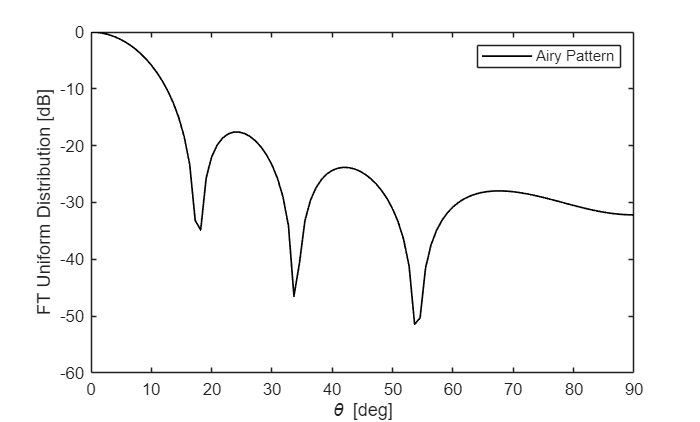

th_ff = linspace(eps, pi/2, 100);
figure;
x = k0*a*sin(th_ff);
airy = 2*pi*a^2 .* besselj(1, x) ./ x;  
airy_max = max(max(20*log10(abs(airy))));

plot(rad2deg(th_ff), 20*log10(abs(airy)) - airy_max, 'k', 'LineWidth', 1);
xlabel('\theta [deg]'); ylabel('FT Uniform Distribution [dB]')
legend('Airy Pattern');

Comparing to the airy pattern, it can be observed that the actual far field is decaying much faster than the airy pattern, which suggests a high current density in the middle of the aperture. Therefore, we would expect a low taper efficiency in the end. 

4. (3 point) Plot the taper, spillover, and aperture efficiencies vs the diameter 𝐷 of the reflector for 0.6 < 𝑓/𝐷 < 6 in linear scale. Explain how different 𝑓/𝐷 values influenced these efficiencies. What criteria leads to the maximum aperture efficiency in this plot?

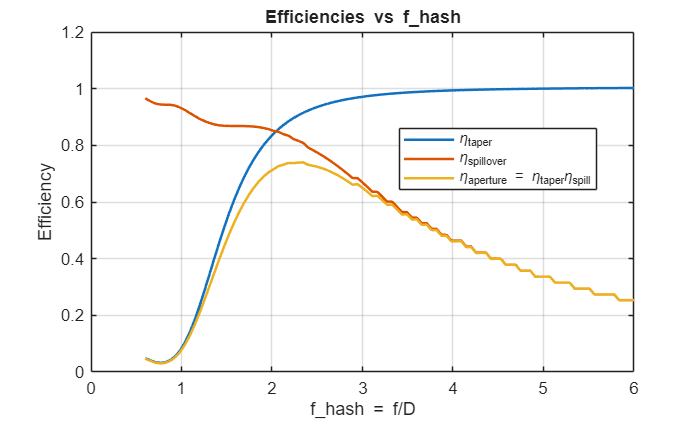

clear; clc;

%% Constants 
f = 500e9;
c0 = 3e8;
lambda_0 = c0 / f;
k0 = 2*pi / lambda_0;
k  = k0;

zeta0 = 120*pi;

D_f = 4*lambda_0;
a   = D_f/2;
J_f = 1;

f_focal = 5;             
num_th  = 401;
num_ph  = 401;

%% Sweep setup
fhash_vec = linspace(0.6, 6, 100);  
D_vec = f_focal ./ fhash_vec;
eta_taper_vec = zeros(size(fhash_vec));
eta_spill_vec = zeros(size(fhash_vec));
eta_ap_vec    = zeros(size(fhash_vec));

%% Predefine phi grids 
phi_taper = linspace(eps, 2*pi, num_ph);
phi_spill = linspace(eps, 2*pi, num_ph);

%% Loop over f_hash
for ii = 1:numel(fhash_vec)
    f_hash = fhash_vec(ii);

    D   = D_vec(ii);
    th0 = 2 * acot(4 * f_hash);

    %% TAPER EFFICIENCY
    theta_taper = linspace(eps, th0, num_th);
    [TH1, PH1, E_theta1, E_phi1] = feed_fields(theta_taper, phi_taper, k0, a, zeta0, J_f);

    % Cylindrical mapping 
    RHO_p = 2 .* f_focal .* tan(TH1 ./ 2);
    PH_p  = PH1;

    phase_ap = exp(-1j*k*2*f_focal) .* (cos(TH1/2).^2) / f_focal;

    Ea_rho = -E_theta1 .* phase_ap;
    Ea_phi = -E_phi1   .* phase_ap;

    Ea_x = Ea_rho.*cos(PH_p) - Ea_phi.*sin(PH_p);
    Ea_y = Ea_rho.*sin(PH_p) + Ea_phi.*cos(PH_p);

    E_a = zeros([size(Ea_x), 3]);   
    E_a(:,:,1) = Ea_x;
    E_a(:,:,2) = Ea_y;

    % Integration steps 
    dth  = (th0)/(num_th-1);
    dphi = (2*pi)/(num_ph-1);
    drho = 2 .* f_focal .* tan(dth ./ 2);

    int_vec = sum(sum(E_a .* RHO_p, 1), 2) * drho * dphi;  
    numerator_sq = abs(sum(int_vec, 3)).^2;

    integrand_den = sum(abs(E_a).^2, 3);
    denominator   = sum(sum(integrand_den .* RHO_p)) * drho * dphi;

    A = pi * (D/2)^2;
    eta_taper = (1/A) * numerator_sq / denominator;

    %%SPILLOVER EFFICIENCY
    theta_spill = linspace(eps, pi/2, num_th);
    [TH2, ~, E_theta2, E_phi2] = feed_fields(theta_spill, phi_spill, k0, a, zeta0, J_f);

    E_mag  = sqrt(abs(E_theta2).^2 + abs(E_phi2).^2);
    U_feed = (1/(2*zeta0)) .* (abs(E_mag).^2) .* sin(TH2);  % r=1 as before

    U_cap = U_feed;
    U_cap(TH2 > th0) = 0;

    dth_feed = (pi/2)/(num_th-1);
    dph_feed = (2*pi)/(num_ph-1);

    eta_spill = (sum(U_cap,'all')*dth_feed*dph_feed) / (sum(U_feed,'all')*dth_feed*dph_feed);

    %% Store
    eta_taper_vec(ii) = real(eta_taper);      
    eta_spill_vec(ii) = real(eta_spill);
    eta_ap_vec(ii)    = eta_taper_vec(ii) * eta_spill_vec(ii);
end

%% Plot
figure;
plot(fhash_vec, eta_taper_vec, 'LineWidth', 1.5); hold on;
plot(fhash_vec, eta_spill_vec, 'LineWidth', 1.5);
plot(fhash_vec, eta_ap_vec,    'LineWidth', 1.5);
grid on;
xlabel('f\_hash = f/D');
ylabel('Efficiency');
legend('\eta_{taper}', '\eta_{spillover}', '\eta_{aperture} = \eta_{taper}\eta_{spill}', 'Location','best');
title('Efficiencies vs f\_hash');

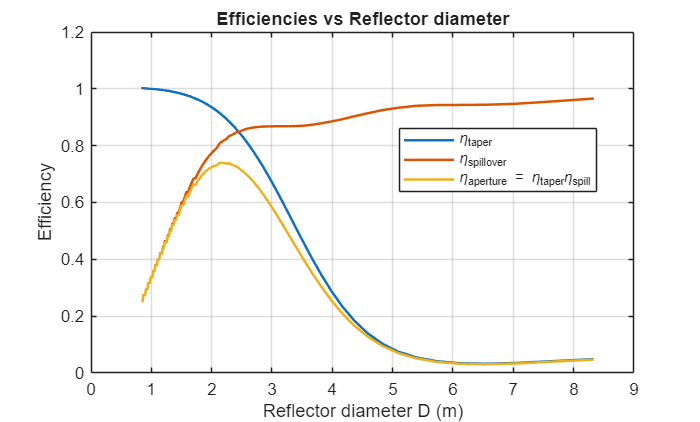

%% Plot
figure;
plot(D_vec, eta_taper_vec, 'LineWidth', 1.5); hold on;
plot(D_vec, eta_spill_vec, 'LineWidth', 1.5);
plot(D_vec, eta_ap_vec,    'LineWidth', 1.5);
grid on;
xlabel('Reflector diameter D (m)');
ylabel('Efficiency');
legend('\eta_{taper}', '\eta_{spillover}', '\eta_{aperture} = \eta_{taper}\eta_{spill}', 'Location','best');
title('Efficiencies vs Reflector diameter');


%% --------- Local function  ---------
function [TH, PH, E_theta, E_phi] = feed_fields(theta_vec, phi_vec, k0, a, zeta0, J_f)
    [TH, PH] = meshgrid(theta_vec, phi_vec);

    r = 1;

    x = k0*a*sin(TH);
    J_FT = 2*pi*a^2 .* besselj(1, x) ./ x;

    pref = (-2*1j*k0*zeta0*J_f) .* J_FT .* exp(-1j*k0*r) ./ (4*pi*r);

    E_theta = pref .* (cos(TH) .* sin(PH));
    E_phi   = pref .* (cos(PH));
end


We can see a clear trade-off between spillover efficiency and taper efficiency: as taper efficiency goes up the current density will be more uniform. However, this leads to a higer leakage outside of $\theta_0$ and leads to a lower spillover efficiency. To find the maximum aperture efficiency, we can take the derivative of the curve and find the point where it equals to 0. In this case, when $f_# =\frac{f_{\mathrm{focal}} }{D}\approx 2\ldotp 29$, we have the maxinimum aperture efficiency.

5. (2 point) Plot the maximum possible directivity (i.e. for a uniform aperture distribution), directivity and gain of the reflector antenna vs the diameter 𝐷 for 0.6 < 𝑓/𝐷 < 6 in dBi. Explain how different 𝑓/𝐷 values influenced these parameters.

For a uniform aperture distribution, we can simply apply Airy pattern. 

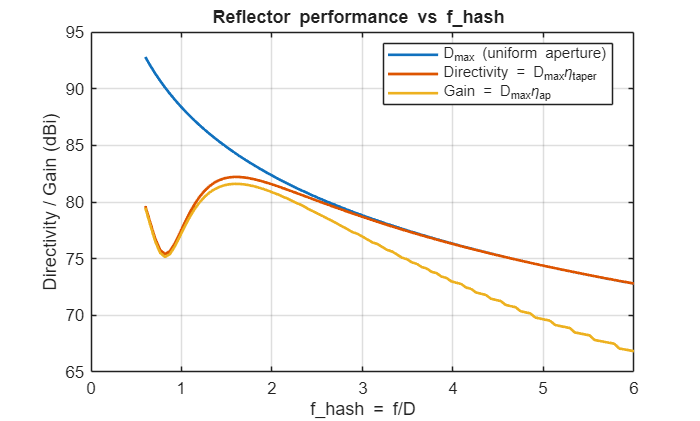

D = f_focal ./ fhash_vec;
A = pi .* (D / 2) .^ 2;
D_max = 4 * pi / lambda_0^2 .* A;
Dir = D_max .* eta_taper_vec;
G = D_max .* eta_ap_vec;

% --- Convert to dBi ---
eps_floor = 1e-300;  % prevents log of 0
Dmax_dBi = 10*log10(max(D_max, eps_floor));
Dir_dBi  = 10*log10(max(Dir,   eps_floor));
G_dBi    = 10*log10(max(G,     eps_floor));

% --- Sort by diameter for nicer plots ---
[D_sorted, idx] = sort(D, 'ascend');

Dmax_dBi_s = Dmax_dBi(idx);
Dir_dBi_s  = Dir_dBi(idx);
G_dBi_s    = G_dBi(idx);

% --- Plot ---
figure;
plot(fhash_vec, Dmax_dBi, 'LineWidth', 1.6); hold on;
plot(fhash_vec, Dir_dBi,  'LineWidth', 1.6);
plot(fhash_vec, G_dBi,    'LineWidth', 1.6);
grid on;
xlabel('f\_hash = f/D');
ylabel('Directivity / Gain (dBi)');
legend('D_{max} (uniform aperture)', 'Directivity = D_{max}\eta_{taper}', ...
       'Gain = D_{max}\eta_{ap}', 'Location', 'best');
title('Reflector performance vs f\_hash ');

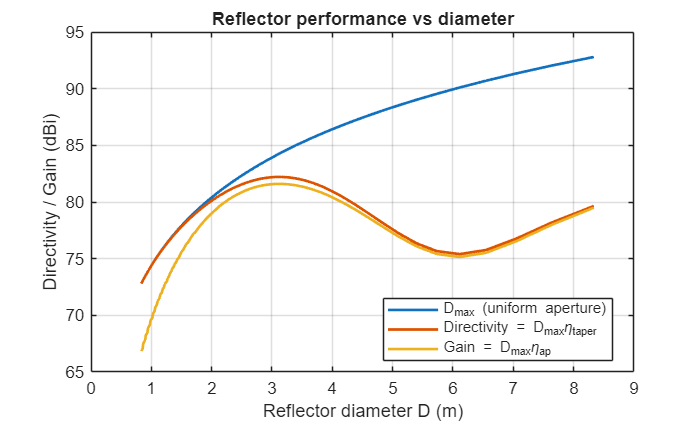


figure;
plot(D_sorted, Dmax_dBi_s, 'LineWidth', 1.6); hold on;
plot(D_sorted, Dir_dBi_s,  'LineWidth', 1.6);
plot(D_sorted, G_dBi_s,    'LineWidth', 1.6);
grid on;
xlabel('Reflector diameter D (m)');
ylabel('Directivity / Gain (dBi)');
legend('D_{max} (uniform aperture)', 'Directivity = D_{max}\eta_{taper}', ...
       'Gain = D_{max}\eta_{ap}', 'Location', 'best');
title('Reflector performance vs diameter');

As we can see in Q4, as f/D increases, the taper efficiency goes up and spillover efficiency goes down. As we can see in the figures in Q5, as f/D increases, the directivity becomes closer to the D_max. However, the mismatch between the gain and directivity becomes larger as f/D increases. D_max only depends on the diameter for the uniform aperture distribution, since we have a fixed focal length, the max directivity will decrease as  f/D increases.